desired_power_input_dBm = -128;
desired_power_input_dBm_array = [-130.5, -128, -125, -122, -119, -116];

% load(['D:\Academics\E-Books\Dartmouth\Rimberg Lab\Data\Sample Design\q_fit_finder\q_fit_values_discreet_bias_values.mat']);
% flux_array = reshape(bias_point_array_ng_1(:, 2), 6, 6);
% ng_array = reshape(bias_point_array_ng_1(:, 1), 6, 6);

ng_array = linspace(0, 0.75, 15);
flux_array = linspace(0, 0.25, 15);
for ng_number = 1 : 15
    for flux_number = 1: 15
%         ng_value = bias_point_array_ng_1(flux_number + (ng_number - 1) *6, 1);
%         flux_value = bias_point_array_ng_1(flux_number + (ng_number - 1) *6, 2);
        ng_value = ng_array(ng_number);
        flux_value = flux_array(flux_number);
        
        [kappa_int, kappa_ext, omega_0]= find_q_fit_values(ng_value, flux_value);
        kappa_int = 0.4;
        kappa_ext = 1.2;
        kappa_int = kappa_int*1e6;
        kappa_ext = kappa_ext*1e6;
        omega_0 = omega_0*1e9;
        kappa_tot = kappa_ext + kappa_int;% 1.5e6; %kappa_int = 0.2265MHz. These values correspond to ng = 0 and phi = 0 for Jules' sample in March 2021 small fridge
        % kerr = 0;
        kerr = 1e6*find_kerr_MHz_ng_flux(ng_value,flux_value);
        detunings = linspace(-45e6, 5e6, 51);
        h = 6.626e-34; % just h, not hbar since omega_0 is in Hz
        plot_figures = 1;
        input_attenuation = 82.9; 
        power_input_start_dBm = -61.2 -input_attenuation; 
        power_input_stop_dBm = -32.1 -input_attenuation; % input_attenuationdB is approx fridge attenuation. 
        power_input_start_watts = 1e-3.*10.^(power_input_start_dBm/10);
        power_input_stop_watts = 1e-3.*10.^(power_input_stop_dBm/10);
        
        % power_input_in_watts = linspace(power_input_start_watts, power_input_stop_watts, 5);
        % power_input_in_dBm = 10*log10(power_input_in_watts/1e-3);
        
        power_input_in_dBm = linspace(power_input_start_dBm, power_input_stop_dBm, 100);
        power_input_in_watts = 1e-3.*10.^(power_input_in_dBm/10);
        
        for i= 1 : length(desired_power_input_dBm_array)
            [~, desired_input_power_number_array(i)] = min(abs(power_input_in_dBm - desired_power_input_dBm_array(i)));    
        end
        [~, desired_input_power_number] = min(abs(power_input_in_dBm - desired_power_input_dBm));
        
        power_input_in_numbers = power_input_in_watts/h/omega_0;
        kerr = kerr/1e6;
        kappa_ext = kappa_ext /1e6;
        kappa_tot = kappa_tot/ 1e6;
        detunings = detunings/ 1e6;
        power_input_in_numbers = power_input_in_numbers/1e6;
        [detunings_array, power_input_array] = meshgrid(detunings, power_input_in_numbers);
        bifurcation_detuning = zeros([size(detunings_array,1), 2]);
        amp_roots = zeros([size(detunings_array),3]);

        for i = 1: size(detunings_array,1)
            for j = 1: size(detunings_array,2)
                amp_roots(i,j,:) = roots([kerr^2, -2*kerr.*detunings_array(i,j), (detunings_array(i,j).^2 + kappa_tot^2 / 4),...
                    -kappa_ext * power_input_array(i,j)]);
            end
        end

        amp_roots(imag(amp_roots) ~=0) = 0;
        main_s11_forward = zeros([size(detunings_array)]);
        main_s11_reverse = zeros([size(detunings_array)]);
        main_s11_forward_power = zeros([size(detunings_array)]);
        main_s11_reverse_power = zeros([size(detunings_array)]);
        first_zero_root_1 = zeros(size(detunings_array,1),1);
        first_zero_root_3 = zeros(size(detunings_array,1),1);

        detunings_array_reps = repmat(detunings_array, [1, 1, 3]);
        s11 = ((detunings_array_reps - kerr .* amp_roots) - 1i*(kappa_tot -...
        2*kappa_ext)/2)./((detunings_array_reps - kerr .* amp_roots) -1i*kappa_tot/2);
        s11(amp_roots == 0) = 5;
        for i = 1: size(detunings_array,1)
            number_zeros_1 = sum(double(amp_roots(i,:,1) == 0));
            number_zeros_3 = sum(double(amp_roots(i,:,3) == 0));
            if number_zeros_1 > 0 && number_zeros_3 > 0
                first_zero_root_3(i) = find(amp_roots(i,:,3) == 0, 1) - 1;
                first_zero_root_1(i) = length(amp_roots(i,:,1)) - find(flip(amp_roots(i,:,1) ~= 0),1) + 1;
                bifurcation_detuning_finder_temp = find(amp_roots(i, :, 2) > 0);
                if length(bifurcation_detuning_finder_temp) > 2
                    bifurcation_detuning(i,1) = detunings_array(i, bifurcation_detuning_finder_temp(1));
                    bifurcation_detuning(i,2) = detunings_array(i, bifurcation_detuning_finder_temp(end));
                else
                    bifurcation_detuning(i,1) = NaN;
                    bifurcation_detuning(i,2) = NaN;
                end
                main_s11_reverse_temp = s11(i,:,1);
                s11_3_temp = s11(i,:,3);
                zero_entries = (main_s11_reverse_temp == 5);
                main_s11_reverse_temp(zero_entries) = s11_3_temp(zero_entries);
                main_s11_forward(i,:) = [s11(i,1:first_zero_root_3(i),3), s11(i,first_zero_root_3(i) + 1: first_zero_root_1(i), 1), s11(i,first_zero_root_1(i) + 1: end, 3)]; 
                main_s11_reverse(i,:) = main_s11_reverse_temp;
            else 
                main_s11_forward = s11(:,:,3);
                main_s11_reverse = s11(:,:,3);
            end
        end
        phase_difference_degs(ng_number, flux_number, :, :) = abs(wrapTo360(180/pi*angle(main_s11_forward)) - wrapTo360(180/pi*angle(main_s11_reverse))); 
        kerr_array(ng_number, flux_number) = kerr;
        for i = 1: size(power_input_array,2)
            number_zeros_1 = sum(double(amp_roots(:,i,1) == 0));
            number_zeros_3 = sum(double(amp_roots(:,i,3) == 0));
            if number_zeros_1 > 0 && number_zeros_3 > 0
                first_zero_root_3(i) = find(amp_roots(:,i,3) == 0, 1) - 1;
                first_zero_root_1(i) = length(amp_roots(:,i,1)) - find(flip(amp_roots(:,i,1) ~= 0),1) + 1;
                main_s11_reverse_temp_power = s11(:,i,1);
                s11_3_temp = s11(:,i,3);
                zero_entries = (main_s11_reverse_temp_power == 5);
                main_s11_reverse_temp_power(zero_entries) = s11_3_temp(zero_entries);
                main_s11_forward_power(:,i) = [s11(1:first_zero_root_3(i),i,3); s11(first_zero_root_3(i) + 1: end,i, 1)];         
        %         main_s11_forward_power(:,i) = [s11(1:first_zero_root_3(i),i,3); s11(first_zero_root_3(i) + 1: first_zero_root_1(i),i, 1); s11(first_zero_root_1(i) + 1: end,i, 3)]; 
                main_s11_reverse_power(:,i) = main_s11_reverse_temp_power;
        %     else 
        %         main_s11_forward_power = s11(:,:,3);
        %         main_s11_reverse_power = s11(:,:,3);
            end
        end
    end
end

[sorted_kerr_vector, kerr_index] = sort(abs(kerr_array(:)), 'ascend');
max_phase_diff_point_bias_point = max(squeeze(phase_difference_degs(:,:, desired_input_power_number, :)), [], 3);
max_phase_diff_point_bias_point_vector = max_phase_diff_point_bias_point(:);
kerr_sorted_max_phase_diff_point_bias_point_vector = max_phase_diff_point_bias_point_vector(kerr_index);

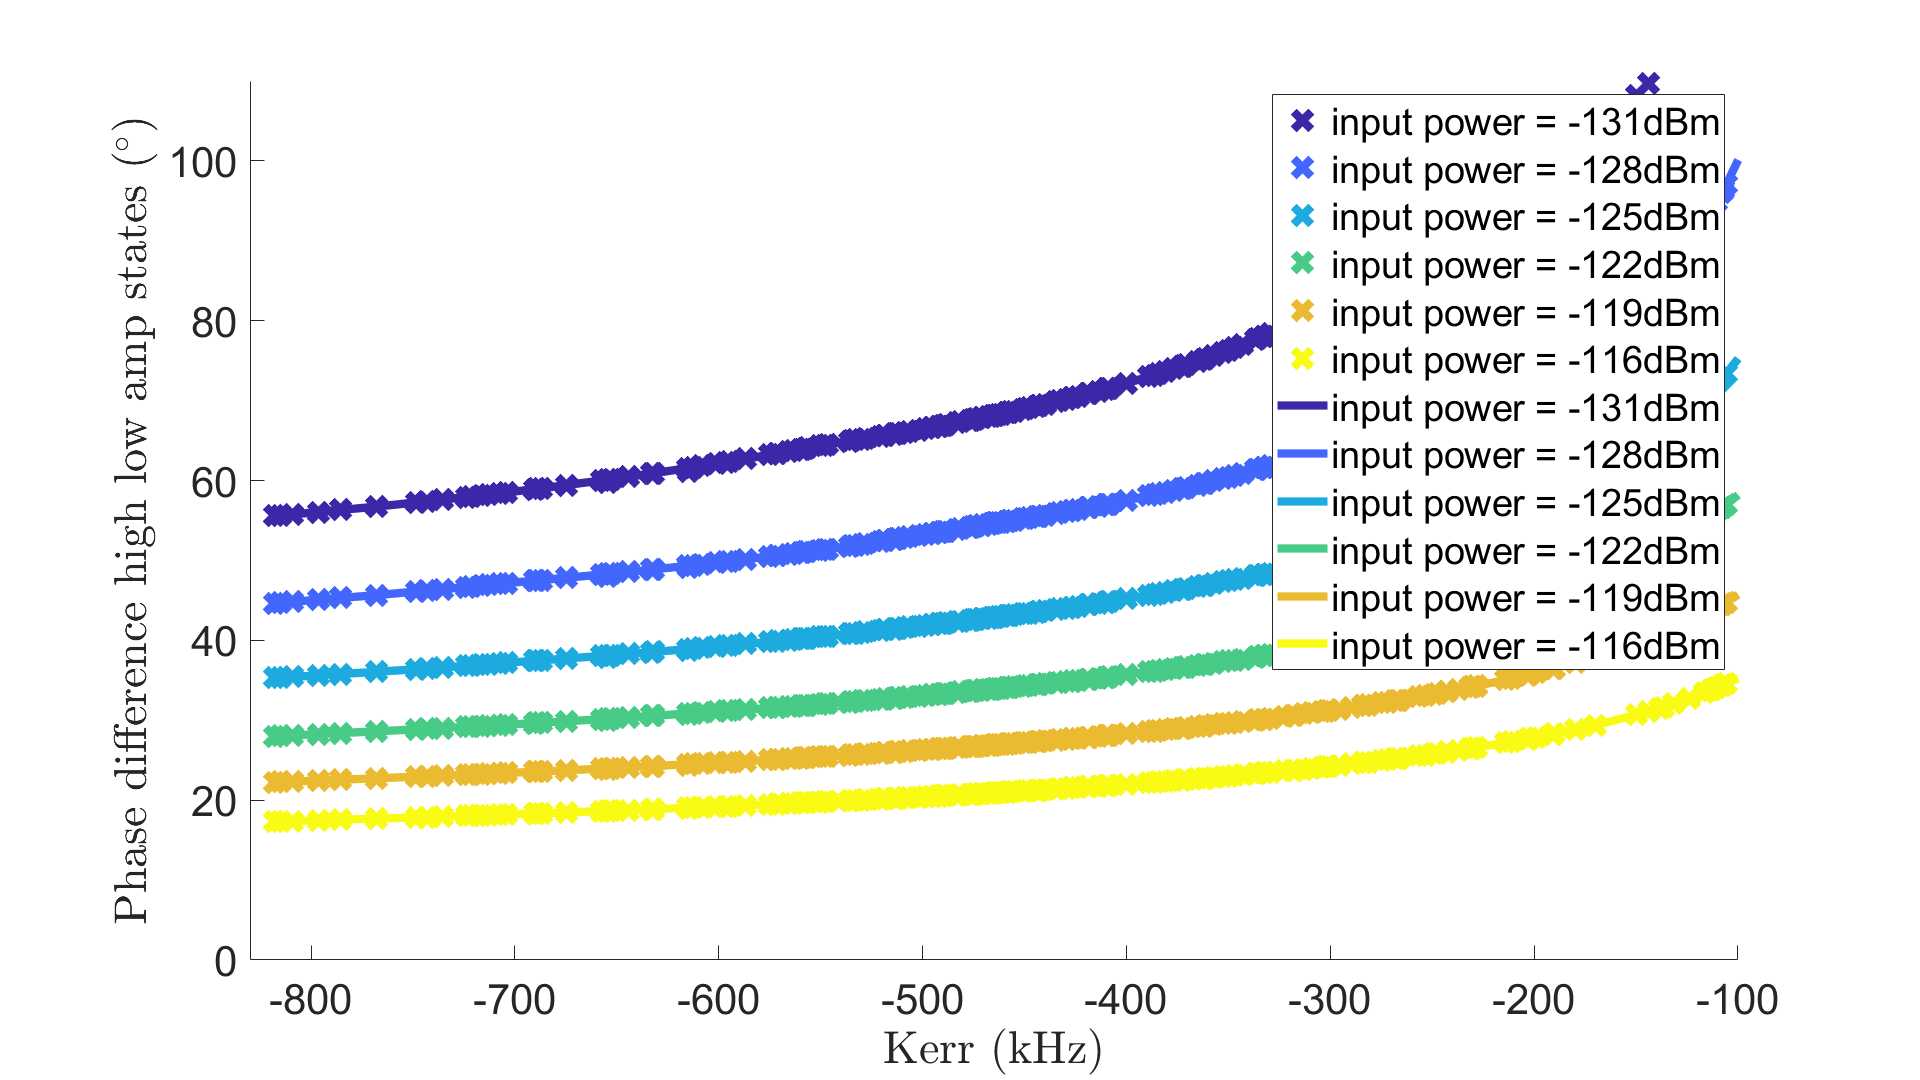

% figure
% surf(ng_array, flux_array, max_phase_diff_point_bias_point')
% view(0,90)
% xlabel('n_g (number of electrons)')
% ylabel('flux')
% title(['theory phase difference between high and low amp states S_{11} for an input power of ' ...
%     num2str(power_input_in_dBm(desired_input_power_number)) 'dBm'])
% colorbar
% min(min(max_phase_diff_point_bias_point))
% max(max(max_phase_diff_point_bias_point))
% mean(mean(max_phase_diff_point_bias_point))
% 
% figure
% surf(ng_array, flux_array, kerr_array')
% view(0,90)
% xlabel('n_g (number of electrons)')
% ylabel('flux')
% colorbar

% figure 
hold on
colors = parula(length(desired_input_power_number_array));
for i = 1 : length(desired_input_power_number_array)
    [sorted_kerr_vector, kerr_index] = sort(abs(kerr_array(:)), 'ascend');
    max_phase_diff_point_bias_point = max(squeeze(phase_difference_degs(:,:, desired_input_power_number_array(i), :)), [], 3);
    max_phase_diff_point_bias_point_vector = max_phase_diff_point_bias_point(:);
    kerr_sorted_max_phase_diff_point_bias_point_vector = max_phase_diff_point_bias_point_vector(kerr_index);
    plot(-sorted_kerr_vector*1e3, 360 - kerr_sorted_max_phase_diff_point_bias_point_vector,'color',...
        colors(i,:),'linewidth', 5, 'displayName', ['input power = ' num2str(round( ...
        power_input_in_dBm(desired_input_power_number_array(i)))) 'dBm'])
    axis([-830, -100, 0 110])
    legend show
    xlabel('Kerr (kHz)', 'interpreter', 'latex')
    ylabel('Phase difference high low amp states ($^\circ$)', 'interpreter', 'latex')
end